# File Manipulation and System Interaction

## Search Path

**Search path** is a subset of all folders on the fie system that MATLAB uses to efficiently locate files used with MathWorks products. All files in the folders on search path can be accessed by MATLAB.

**Order** of folders on search path is important:

When fies in different folders (both in search path) with *same filename *exist, MATLAB uses the one in the folder *nearest the top* of the search path.

Search path includes:

- Folders provided with MATLAB and other MathWorks products

- MATLAB `userpath` (first on search path above folders supplied by MathWorks)

#### `Search Path Commands`

- `addpath:` Add folders to search path

- `rmpath:` Remove folders from search path

- `path:` View or change search path

- `savepath:` Save current search path

- `userpath:` View or change user portion of search path

- `genpath:` Generate path string

- `pathsep: Search path separator for current platform`

## Import/Export Data

### Text File

- `importdata:` Load data from file

- `dlmread: `Read ASCII-delimited fie of numeric data into matrix

- `dlmwrite:` Write matrix to ASCII-delimited file

- `textscan:` Read formatted data from text fie or string

- `type:` Display contents of file

#### Demo

#### The **lift-drag** history for the flow around the **Ahmed body**

The Ahmed body is a generic car body (a simplified vehicle model).

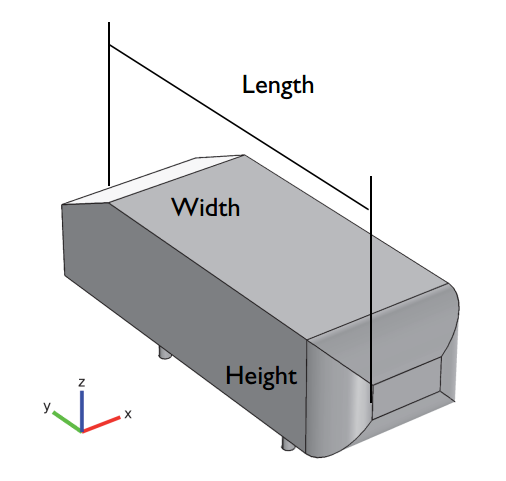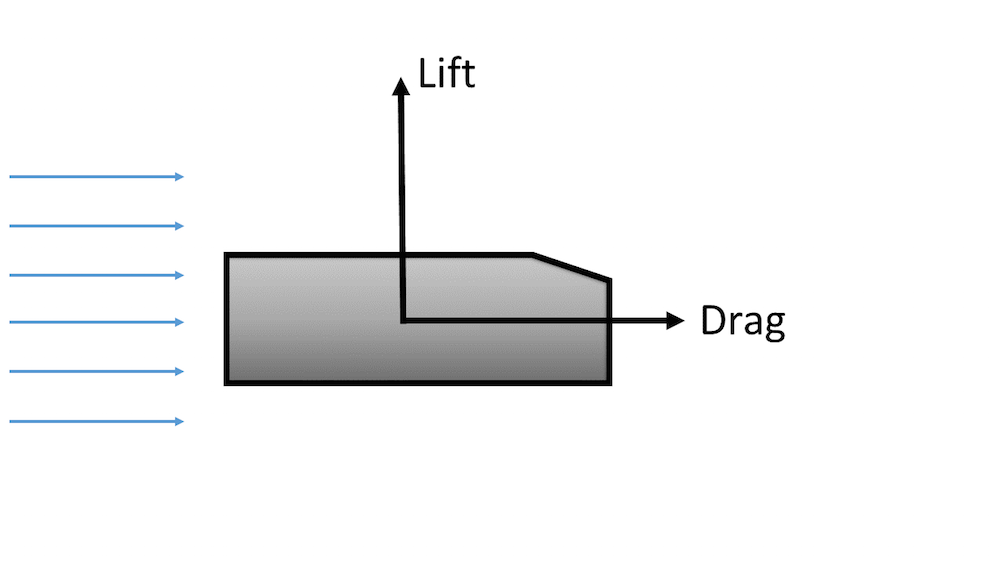

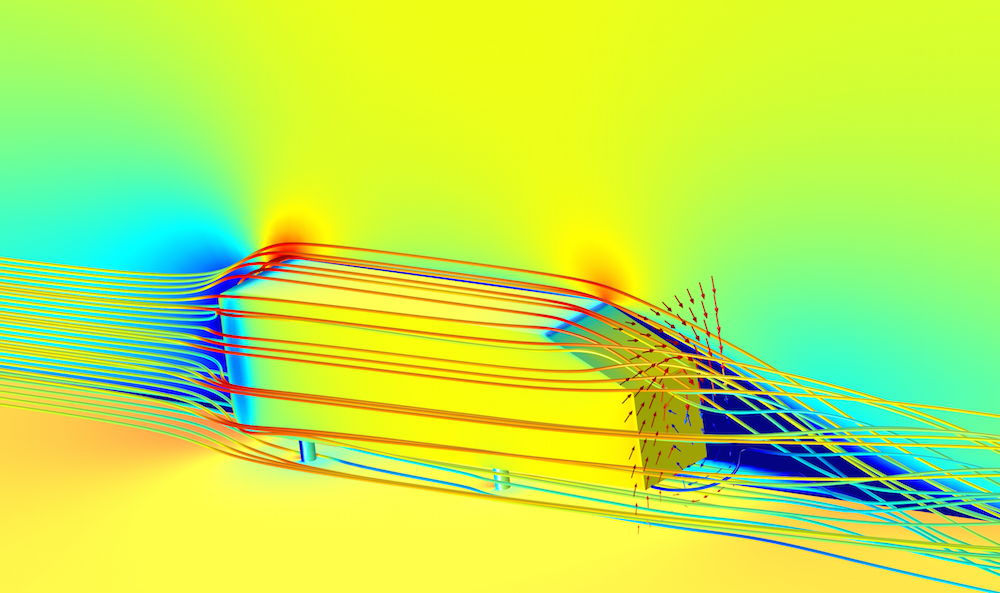

Plots taken from the post [https://www.comsol.com/blogs/studying-the-airflow-over-a-car-using-an-ahmed-body/](https://www.comsol.com/blogs/studying-the-airflow-over-a-car-using-an-ahmed-body/) and [https://www.comsol.com/blogs/how-do-i-compute-lift-and-drag/.](https://www.comsol.com/blogs/how-do-i-compute-lift-and-drag/.)

`dlmread`

`RESULT = dlmread(FILENAME)`

- Delimiter inferred from file format

`RESULT = dlmread(FILENAME,DELIMITER)`

- Delimiter specified by string `DELIMITER` (tabs are `'\t'`)

`RESULT = dlmread(FILENAME,DELIMITER,R,C)`

- `R, C `specify the row/column in file of upper left corner of data (zero-based)

`RESULT = dlmread(FILENAME,DELIMITER,RANGE)`

- `RANGE = [R1,C1,R2,C2]` specifies upper left and lower right corners of data (zero-based)

When a delimiter is inferred from the formatting of the file, *consecutive whitespaces* are treated as a single delimiter. By contrast, if a delimiter is specified by the DELIMITER input, any *repeated delimiter character* is treated as a separate delimiter.

#### Demo

dir('data/liftdrag')
fnames = dir('data/liftdrag')
fname = ['data/liftdrag/',fnames(3).name]

liftdrag = dlmread(fname,' ',1,0)

figure 
% plot the drag history (the 5th column vs. the 2nd column)
h(1)=plot(liftdrag(:,2),liftdrag(:,5),'k-','linew',2);
xlabel('time'); ylabel('drag coefficient');

`dlmwrite`

`dlmwrite(FILENAME,M)`

- Write matrix `M` to file, delimited by `,` 

- If `FILENAME` exists, it will be overwritten

`dlmwrite(FILENAME,M,DELIMITER)`

- Delimiter specified by string `DELIMITER` (tabs are `'\t'`)

`dlmwrite(FILENAME,M,DELIMITER,R,C)`

- `R,C` specify the row/column in file of upper left corner of data (zero-based)

Force `dlmwrite` to *append to existing file* by using the '􀀀`append`' flag

Additional attributes that given to `dlmwrite` that will alter the format of the ASCII file:

- `'delimiter', 'newline', 'roffset', 'coffset', 'precision'`

dlmwrite('unsteady.liftdrag.copy',liftdrag,'\t')

The time history in each of the 5 files corresponds to a different method of solving the CFD problem.

pstr = {'r','b'};
fnames = dir('data/liftdrag');
for i = 1:length(fnames)-2
    fname = ['data/liftdrag/',fnames(i+2).name];
    liftdrag = dlmread(fname,' ',1,0);
    
    if i == 1
        figure();
        h(1)=plot(liftdrag(:,2),liftdrag(:,5),'k-','linew',2); hold on;
    elseif rem(i,2) == 0
        h(end+1)=plot(liftdrag(:,2),liftdrag(:,5),[pstr{floor(i/2)},'--'],'linew',2);
    else
        h(end+1)=plot(liftdrag(:,2),liftdrag(:,5),[pstr{floor(i/2)},':'],'linew',2);
    end
end
xlabel('time'); ylabel('drag coefficient');
leg=legend('Exact','v (e = 0.995)','ROM2 (e = 0.995)','ROM1 (e = 0.998)','ROM2 (e = 0.998)');
set(leg,'Location','northwest');

### Low-Level File Commands

- `fopen:` Open file

- `fclose:` Close one or all open files

- `feof:` Test for end of file

- `ferror:` Information about file IO errors

- `fgetl: `Read line from fie, remove newline character

- `fgets:` Read line from file, keep newline character

- `fileread:` Read contents of file into string

- `textscan:` Read formatted data from text file or string

- `fprintf:` Write data to text file

- `fread:` Read data from binary file

- `frewind: `Move file position indicator to beginning of open file

- `fscanf:` Read data from text file

- `fseek:` Move to specified position in file

- `ftell:` Position in open file

- `fwrite:` Write data to binary file

**Open/Close file**

`FID = fopen(FNAME)`

- Opens the file `FNAME`

- `FID` is a scalar integer valued double, called a **file identifier**

- Use `FID` as the first argument to other file IO routines

- If `fopen` cannot open the file, it returns `-1`

`FID = fopen(FNAME,PERMISSION)`

- Opens the file `FNAME` in the mode specified by `PERMISSION`

- open for reading (`r`), writing (`w`), appending (a) - create if file does not exist

- open for reading (`r+`), writing (`w+`), appending (`a+`) - do not create file

`ST = fclose(FID)`

- Closes the file associated with file identifier `FID`, obtained from `fopen`

- `fclose('all')` closes all open files except standard input, output, and error

**Read line from file**

`TLINE = fgetl(FID)`

- Returns the next line of a file associated with file identifier `FID` as a MATLAB string (identififier incremented)

- Line terminator is NOT included

`TLINE = fgets(FID)`

- Same as `fgetl` with line terminator included

fid = fopen('data/liftdrag/unsteady.hdm.LiftDrag');
line1 = fgetl(fid)
for i = 1:10
%     line = fgetl(fid);
    line = fgets(fid); %try with fgets to see line spacing
    fprintf(line)
end
fclose(fid);

**Write to text file**

`fprintf(FID, FORMAT, A, ...)`

- Applies the `FORMAT` to all elements of array A and any additional array arguments in column order, and writes the data to a text file with file identifier `FID` from `fopen`

- Set `FID` to 1 to print to the screen (or exclude)

year = 8/3;
fprintf('%f year at Stanford\n',year)
fprintf('%10.3f year at Stanford\n',year)
fprintf('%10.15f year at Stanford\n',year)

Conversion Characters

- `%d,%i` Signed integer

- `%u` Unsigned integer

- `%f` Floating point, fixed notation

- `%e` Floating point, exponential notation (`e`)

- `%E` Same as `e` using E

- `%g` Compact form of `e`

- `%G` Compact form of E

- `%c` Single character

- `%s` String of characters

- `''` Single quote (')

- `%%` Percent sign (%)

- `\n` Newline

- `\t` Tab

v = 0.333;
fprintf('%f,\t%e, %E\n%g%% ''demo'' %G\n',v,v,v,v,v)

- `ftell(FID)` returns the position in the file

- `fseek(FID,OFFSET,ORIGIN)` repositions the file position indicator to the byte with the specified `OFFSET` relative to `ORIGIN`

- `frewind(FID)` resets FID to the beginning of the file `FNAME`

- `feof(FID)` returns true if end-of-file indicator has been set

fid = fopen('data/liftdrag/unsteady.hdm.LiftDrag');

fprintf('File location = %d\n',ftell(fid));
fprintf('At end of file? = %d\n',feof(fid));
fseek(fid,1000,-1);
fprintf('File location = %d\n',ftell(fid));
fprintf('At end of file? = %d\n',feof(fid));
frewind(fid);
fprintf('File location = %d\n',ftell(fid));
fprintf('At end of file? = %d\n',feof(fid));
fclose(fid);

#### Quiz.

What is the position of the end of the file? Write a few lines of code to find this out. Consider using the `fgetl` function.

fid = fopen('data/liftdrag/unsteady.hdm.LiftDrag');
while (fgetl(fid)~=-1); end
fprintf("File location = %d\n",ftell(fid));
fprintf('At end of file? = %d\n',feof(fid));

fclose(fid);

**Writing/reading binary files**

*Comparing to text files, binary files require less storage.*

`count = fwrite(FID,A)`

- Writes the elements of matrix A to the specified file

- The data are written in column order

- `count` is the number of elements successfully written.

`A = fread(FID)`

- Reads binary data from the specified file and writes it into matrix A

- Reads the entire file and positions the file pointer at the end of the file

`A = fread(FID,SIZE)`

- Reads the number of elements specified by `SIZE`

- Valid entries for `SIZE` are: `N` - read N elements into a column vector; `inf `- read to the end of the file; `[M,N] `- read elements to fill an M-by-N matrix, in column order (N can be inf, but M can't)

`textscan`

Read *formatted* data from text file or string

`C = textscan(FID,'FORMAT',N)`

- Reads data from the file, using the `FORMAT` (recall conversion characters: `%u, %i, %u, %f, %e, %E, %g, %G, %c, %s`)` N `times, wher`e N `is a positive integer

- To read additional data from the file after` N `cycles, call `textscan` again using the original `FID.`

- Useful when format of file not uniform through the end of the file.

**Demo: (surface) mesh data in the FRG format**

Data from UC Berkeley Computer Graphics group.

- First line of each file contains header information (number of nodes/elements, etc).

- Nodes contained in columns 2 - 4 for nodes file. 

- Elements contained in columns 2 - 5 of elements file.

Extract node data into matrix p and element data into matrix t.

fname = 'data/mesh_ex';

fid = fopen([fname,'.node']);
fgetl(fid);
nodes  = textscan(fid,'%d %f %f %f %d');
fclose(fid);
p = [nodes{2:end-1}];

fid = fopen([fname,'.ele']);
fgetl(fid);
elems  = textscan(fid,'%d %d %d %d %d');
fclose(fid);
t = [elems{2:end}];

Plot the mesh use the provided function `simpplot`:

figure;
simpplot(p,t);
set(gca,'cameraposition',[40.5091 39.0167 488.426],...
        'view',[ 13,72]);

### Spreadsheets 

#### Commands

- `xlsfinfo`: Determine if file contains Microsoft Excel spreadsheet

- `xlsread`: Read Microsoft Excel spreadsheet file

- `xlswrite`: Write Microsoft Excel spreadsheet file

`[STAT, MSG] = xlswrite(FNAME, M, SHEET, RANGE)`

- Writes the data in matrix `M` to the fie `FNAME` in the sheet specified by `SHEET` to the range of cells specified by `RANGE`

- `SHEET` can be numeric specifying worksheet index or quoted string

- `RANGE` is of the form '`X:Y`' where `X` indicates the upper left corner of the writable range and `Y` is the lower right corner (i.e. `'B2:D4'` is the 3-by-3 block of cells from row B to D and columns 2 to 4)

Requires ability to use Excel as COM server; otherwise, saves to CSV file.

xlswrite('data/liftdrag.xls', liftdrag)

Workaround: convert data to a table and use `writetable`

load and format the header

fname = ['data/liftdrag/',fnames(3).name];
fid = fopen(fname);
line1 = fgetl(fid)
fclose(fid);

header = split(line1);
header(end)=[];
header(1) = strip(header(1),'left','#');
header = [{'No'};header]
T = array2table(liftdrag,'VariableNames',header)
writetable(T,'data/liftdrag.xlsx')

`[NUM,TXT,RAW]=xlsread(FILE,SHEET,RANGE)`

- Reads the data specified in `RANGE` from the worksheet `SHEET`, in the Excel file specified in `FILE`.

- The full functionality of `xlsread` depends on the ability to start Excel as a COM server from MATLAB.

`[NUM,TXT,RAW]=xlsread(FILE,SHEET,RANGE,'basic')`

- Uses basic input mode. This is the mode used on UNIX platforms as well as on Windows when Excel is not available as a COM server.

- In this mode, xlsread does not use Excel as a COM server, which limits import ability.

- Without Excel as a COM server, `RANGE` will be ignored and, consequently, the whole active range of a sheet will be imported.

- Also, in basic mode, `SHEET` is case-sensitive and must be a string.

[NUM,TXT,RAW]=xlsread('data/liftdrag.xlsx')

### Image IO

#### Commands

- `imfinfo`: Information about graphics file

- `imread`: Read image from graphics file

- `imwrite`: Write image to graphics file

A = imread('data/palm.png','png');
size(A)
figure; image(A);
imwrite(A,'data/palm.jpeg','jpeg');

## Operating System

`clipboard:` Copy/paste strings to/from sys clipboard

`computer:` Information about computer

`dos:` Execute DOS command and return output

`getenv:` Environment variable

`perl:` Call Perl script

`setenv:` Set environment variable

`system:` Execute operating system command and return output

`unix:` Execute UNIX command and return output

`winqueryreg:` Item from Windows registry

`bang (!):` Shell escape

#### System Calls

Power of operating system available inside MATLAB

Given stand-alone C/C++/Fortran code with files defining inputs and outputs

- Ability to call executable from within MATLAB

- Use MATLAB's file management to write input files and read output files

- Provides non-intrusive alternative to integrating stand-alone code with MATLAB via MEX interface

`[status,result] = system('command')`

- Calls upon the operating system to execute the given command. The resulting status and standard output are returned.

[status,result] = system('ls')